# **Assignment: **Gene Expression 

#### Bianca Caissotti di Chiusano

Some toxicology researchers want to know the effect of Cyclosporin A (CSA) on human cells. They take two doses of this compound (20uM and 3uM) and take samples after 12, 24, 48 and 72 hours of exposure. They also take samples from cells exposed to just the solvent which the CSA is normally dissolved into, DMSO (eg the samples labelled DMSO are untreated and the samples labelled CSA are treated). They want to know which genes are affected by the CSA.  

- After preprocessing (as above) pick at least one dose/timepoint combination and find the differentially expressed genes.

The data for this task is in the file raw_data_labelled.csv the rows are labelled with the affymetrix id of the probe - there will be many probes measuring each gene.  

Reading the table:

data = readtable("raw_data_labelled.csv")

data = 54675×37 table
          Var1          DMSO_12h_1    CsA_20uM_12h_1    CsA_3uM_12h_1    DMSO_24h_1    CsA_20uM_24h_1    CsA_3uM_24h_1    DMSO_48h_1    CsA_20uM_48h_1    CsA_3uM_48h_1    DMSO_72h_1    CsA_20uM_72h_1    CsA_3uM_72h_1    DMSO_12h_2    CsA_20uM_12h_2    CsA_3uM_12h_2    DMSO_24h_2    CsA_20uM_24h_2    CsA_3uM_24h_2    DMSO_48h_2    CsA_20uM_48h_2    CsA_3uM_48h_2    DMSO_72h_2    CsA_20uM_72h_2    CsA_3uM_72h_2    DMSO_12h_3    CsA_20uM_12h_3    CsA_3uM_12h_3    DMSO_24h_3    

The data needs to be transformed into log base 2, and we do this with the following command:

base2data = log2(table2array(data(1:54675, 2:37)))

base2data =    10.1954    9.4686    9.6357   10.0375    9.9174    9.7013    9.2503    9.7288    9.6961    9.4543   10.1344    9.4656    9.9315    9.9069    9.8289    9.3772    9.7912    9.8345    9.5736   10.2986    9.9359    9.4126    9.7515    9.5018   10.0828    8.9986    9.7313    9.8057    9.6366    9.6448    9.5755    9.7557    9.7465    9.3696    9.8549    8.9873
    9.6055    7.9858    8.8424    9.0224    8.0417    8.6202    7.6900    7.5196    7.7211    7.4512    8.1472    7.7944    9.3945    8.2384    8.9844    8.6092    8.1137    8.5216    8.2644    8.4388    8.1033    7.9039    7.8549    7.8138    9.0620    7.8918    9.1749    8.9830    7.9600    8.8392    8.2095    7.9337    8.2384    7.7582    7.7074    7.5699
    7.4094    6.7879    6.4757    7.2288    7.6795    6.8704    6.8765    7.6724    6.8138    6.7074    7.9658    6.8580    7.0279    7.0607    6.9129    6.9307    8.2946    6.9887    6.9189    8.4512    7.2527    7.1649    7.7448    6.9009    6.9425    6.6366    7.

This is how I understood the data: 

We have three samples, one with untreated cells (DMSO) and two with treated cells (CSA 20 and CSA 3). For each of these samples we measure after 12, 24, 48 and 72 hours. This would make up for 12 columns of data (3 x 4). But we repeat this 3 times, ending up with 36 samples.

Here we make a boxplot to show the range of values for each of the 36 samples

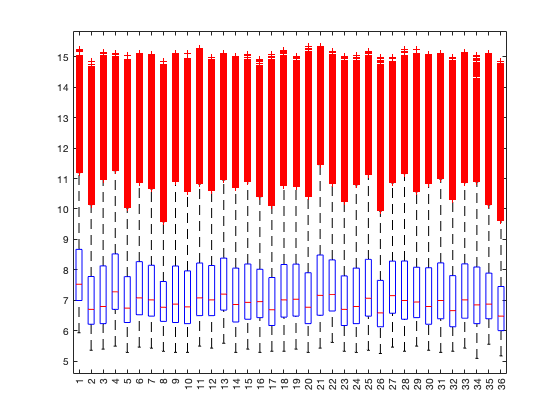

figure;
boxplot(base2data)

As it can be observed the data is in need of normalisation, and this has to be done before comparing samples and running experiments. In Gene Expression analysis, Normalisation is needed because some "chips may have an overall higher or lower instensity than others". In other words, we want the low expressed genes to have equal "weights" as the high expressed genes.

We normalise using the **quantilenorm** command:

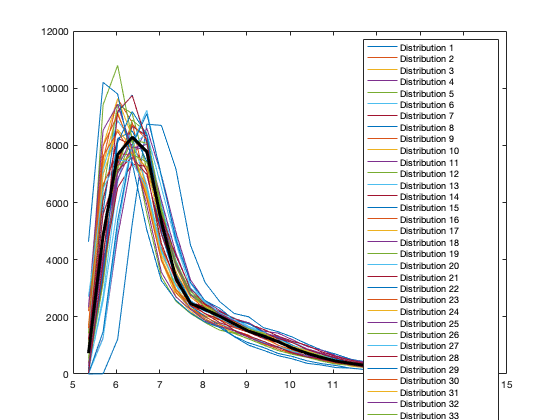

normalised = quantilenorm(base2data, 'MEDIAN', true, 'DISPLAY', true);

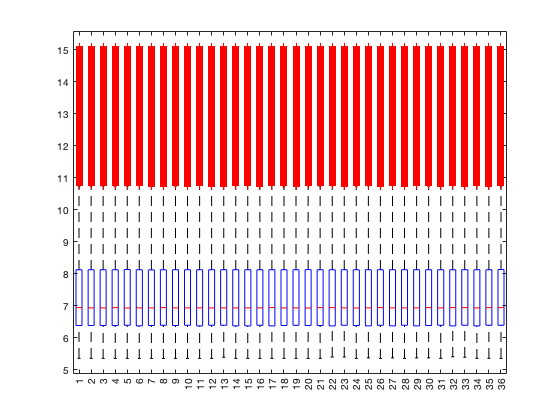

figure;
boxplot(normalised)

% Cutoff when the guaussian ends
% Gaussian is the noise distrubution (unexpressed genes)
% One is guassian the other one is log % Right now they are overlapping

As we saw in class, the data has two distributions of values, one of the expressed genes and one of the unexpressed genes.

To see the overlapping distributions we do a histogram of the normalised data.

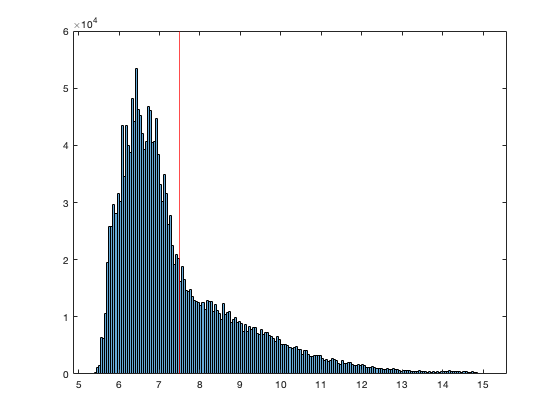

figure;
histogram(normalised)
cutoff = 7.5;
hold on
xline(cutoff, 'Color', 'Red')
hold off

A cutoff has to be chosen to eventually filter out the unexpressed genes from the data. Looking at the histogram I was undecided whether choosing a cutoff of 7.3 or 7.5, but I ended up choosing 7.5 to really avoid any unexpressed genes for later comparing.

This vector time is constructed so that it is easier in the future to quickly extract the right samples when chosing the timepoints.

time = [12,12,12,24,24,24,48,48,48,72,72,72,12,12,12,24,24,24,48,48,48,72,72,72,12,12,12,24,24,24,48,48,48,72,72,72];
% Example
trial = normalised(:, time==12)

trial =     9.6635    9.7830    9.5314    9.6447    9.8353    9.6830    9.7863    9.4051    9.5878
    9.0607    8.3332    8.7748    9.1176    8.2969    8.8734    8.7912    8.3663    9.0112
    6.8265    7.0334    6.6366    6.7681    7.1344    6.9159    6.8265    7.0000    6.9600
    9.0028    8.6456    8.8265    8.8796    8.6339    8.9915    8.8471    8.6635    8.8750
    6.0980    6.0552    5.7944    6.0768    6.1799    5.9657    6.0552    5.9425    5.8948
    7.4798    7.4918    7.4179    7.5430    7.3923    7.6330    7.3531    7.1749    7.6036
    7.5469    7.1997    7.3083    7.4594    6.9830    7.3837    7.1997    7.0553    7.1699
    6.7879    7.2668    6.8265    6.7681    7.2384    6.6900    6.8642    6.6073    6.7944
    6.0980    6.2191    5.8703    6.2854    6.2095    6.0112    6.0768    5.9657    6.1799
    5.9657    6.0112    6.3750    6.0552    5.9657    6.1395    6.0980    6.2668    5.9305


Getting the expressed genes and filtering out the unexpressed genes:

The keep track array holds the position of the expressed genes from the original normalised data. A gene is expressed if it has a value above the cutoff 7.5 (that was previously chosen) in all samples from (at least) a single timepoint.

It counted 16738 expressed genes in an initial data set of 54675 genes

keep_track = [];
count = 0;
for j = 1: length(normalised)
    if all(normalised(j, time==12)>cutoff) || all(normalised(j, time==24)>cutoff) || all(normalised(j, time==48)>cutoff) || all(normalised(j, time==72)>cutoff)
         count = count + 1;
         keep_track(end+1) = j;
    end 
end
count

count = 16738

I ran three experiments, looking at which of the expressed genes are differentially expressed after 12, 36 and 60 hours by calculating the fold change and ttest p-value (fdr corrected). Thus we are going to compare the expressed genes from time step 12 to time steps 24, 48 and 72 respectively.

The beginning of each experiment is the same (code wise), thus I will explain the implementation only for the first experiment.

### Experiment 1: Difference between time 12 and time 24 (12 hours)

With Fold change we are looking at how the expressed genes change on average within the experimental conditions, so we take the mean or average of the expressed genes at that time and calculate their difference.

expressed = normalised(keep_track,:)

expressed =     9.6635    9.7830    9.5314    9.5943   10.1402    9.5651    9.2819   10.3575    9.7009    9.6751    9.9968    9.5142    9.6447    9.8353    9.6830    9.5372   10.0161    9.8025    9.5498   10.3520    9.5294    9.2679   10.0317    9.5660    9.7863    9.4051    9.5878    9.5594    9.6613    9.6389    9.4656    9.9344    9.6698    9.3912   10.0553    9.8082
    9.0607    8.3332    8.7748    8.5906    8.3923    8.4757    7.6110    8.0056    7.7108    7.5698    8.0485    7.7381    9.1176    8.2969    8.8734    8.7398    8.4818    8.4778    8.2095    8.6420    7.7481    7.6546    8.1849    7.8734    8.7912    8.3663    9.0112    8.7615    8.0000    8.8595    8.1085    8.2432    8.1724    7.7715    7.9129    8.2668
    9.0028    8.6456    8.8265    8.8857    8.6420    8.8887    8.9144    8.7715    8.9658    8.8580    8.7347    8.7863    8.8796    8.6339    8.9915    9.1006    8.5699    8.9203    8.9915    8.5718    8.9009    8.8423    8.6036    8.8455    8.8471    8.6635    8.

time_12 = expressed(:,time==12);
time_24 = expressed(:,time==24);

fold_changes = {};
for i = 1: length(time_12)
    diff_mean = mean(time_24(i,:))-mean(time_12(i,:));
    fold_changes = [fold_changes, diff_mean];
end
fold_changes = cell2mat(fold_changes)

fold_changes =     0.0661   -0.2051    0.0307    0.1919    0.0081    0.0269    0.1590    0.1299    0.0113   -0.1217    0.0827   -0.1030    0.0392   -0.1407   -0.0850   -0.0255   -0.1825    0.1359   -0.2297    0.0099   -0.1313    0.4038    0.3166   -0.0167   -0.1951    0.0371   -0.0930    0.0359    0.2314    0.3697    0.1298   -0.0154   -0.0614    0.0643   -0.0504    0.0021    0.0978   -0.1712    0.0126   -0.2862   -0.0890    0.2143    0.2585   -0.0759    0.0169    0.0819    0.0613   -0.0815    0.0252   -0.0976


We also want to look at the statistical significance of the change, taking into account the variance of the change measured.

We start by performing a t-test to calculate the p-value

ttest2 is a two sample t test. This command can return the null hypothesis h and the p-value. "The result `h` is `1` if the test rejects the null hypothesis at the 5% significance level, and `0` otherwise."(from documentation)

[h,p] = ttest2(time_12', time_24')

h =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     1     0     0     0     0     0     1     1     0     0     0     0     0     0     0     1     0     0     0     1     1     0     0     0     0     0     0     0


p =     0.4520    0.1550    0.6975    0.0686    0.9342    0.6545    0.2625    0.3600    0.9700    0.3942    0.4276    0.3460    0.5365    0.5244    0.6897    0.6959    0.1948    0.2194    0.0103    0.8642    0.1686    0.2873    0.0326    0.8165    0.1465    0.5141    0.3934    0.8533    0.0183    0.0108    0.1623    0.8953    0.6928    0.7081    0.7101    0.9855    0.1011    0.0112    0.8934    0.3387    0.2977    0.0433    0.0459    0.5546    0.9179    0.4890    0.3306    0.6313    0.8084    0.7298


From the data the null hypothesis is usually not rejected.

But we first need to adjust the p-value with the FDR correction. If we don't do this we can get many false positive results.

adjusted_p = mafdr(p,'BHFDR','true')

adjusted_p =     0.8016    0.5507    0.9079    0.3960    0.9806    0.8914    0.6726    0.7452    0.9915    0.7684    0.7885    0.7371    0.8433    0.8378    0.9043    0.9071    0.6025    0.6327    0.1733    0.9622    0.5704    0.6917    0.2893    0.9477    0.5387    0.8326    0.7679    0.9591    0.2250    0.1774    0.5621    0.9700    0.9056    0.9114    0.9123    0.9963    0.4657    0.1807    0.9696    0.7327    0.7014    0.3256    0.3316    0.8505    0.9770    0.8228    0.7276    0.8829    0.9453    0.9189


upregulated = {};
downregulated = {};
for i=1:length(fold_changes)
    if fold_changes(i) > 1 && adjusted_p(i) < 0.05
        upregulated = [upregulated,adjusted_p(i)];
    end
    if fold_changes(i) < -1 && adjusted_p(i) < 0.05
        downregulated = [downregulated,adjusted_p(i)];
    end
end

From the lecture material, we know that genes are differentially expressed if they have a high fold change and are significant.

Upregulation is when a cell increases its response to a substance. And downregulation is the opposite. In other words Upregulated is also when the fold change of a gene is greater that 1 and is significant --> thus a differentially expressed gene.

From both upregulated and downregulated genes, we can see that after 12 hours there are not many changes.

upregulated

upregulated = 1×1 cell array
    {[0.0356]}


downregulated

downregulated = 1×1 cell array
    {[0.0413]}


I also wanted to see what results I would get from not adjusting the p-value in this experiment:

upregulated = {};
downregulated = {};
for i=1:length(fold_changes)
    if fold_changes(i) > 1 && p(i) < 0.05
        upregulated = [upregulated,p(i)];
    end
    if fold_changes(i) < -1 && p(i) < 0.05
        downregulated = [downregulated,p(i)];
    end
end
upregulated

upregulated = 1×2 cell array
    {[4.8156e-04]}    {[9.6894e-04]}


downregulated

downregulated = 1×2 cell array
    {[6.6159e-04]}    {[0.0049]}


### Experiment 2: Difference between time 12 and time 48 (36 hours)

time_48 = expressed(:,time==48);

fold_changes = {};
for i = 1: length(time_12)
    diff_mean = mean(time_48(i,:))-mean(time_12(i,:));
    fold_changes = [fold_changes, diff_mean];
end
fold_changes = cell2mat(fold_changes);
[h,p] = ttest2(time_12', time_48');
adjusted_p = mafdr(p,'BHFDR','true');

upregulated = {};
downregulated = {};
for i=1:length(fold_changes)
    if fold_changes(i) > 1 && adjusted_p(i) < 0.05
        upregulated = [upregulated,adjusted_p(i)];
    end
    if fold_changes(i) < -1 && adjusted_p(i) < 0.05
        downregulated = [downregulated,adjusted_p(i)];
    end
end
upregulated

upregulated = 1×85 cell array
    {[0.0042]}    {[9.7597e-04]}    {[1.4218e-04]}    {[3.4513e-04]}    {[1.4660e-07]}    {[1.2113e-04]}    {[0.0064]}    {[1.0015e-05]}    {[3.2735e-06]}    {[0.0037]}    {[0.0169]}    {[0.0471]}    {[0.0116]}    {[0.0203]}    {[0.0063]}    {[4.7011e-08]}    {[0.0048]}    {[4.3530e-06]}    {[5.9326e-04]}    {[0.0038]}    {[4.6232e-04]}    {[0.0051]}    {[0.0144]}    {[0.0252]}    {[0.0340]}    {[0.0077]}    {[4.2913e-05]}    {[3.7390e-04]}    {[7.6796e-04]}    {[1.9600e-04]}    {[1.1530e-04]}    {[2.7299e-04]}    {[1.5739e-04]}    {[0.0037]}    {[9.2751e-04]}    {[3.2980e-05]}    {[0.0096]}    {[8.6509e-05]}    {[0.0018]}    {[3.4784e-04]}    {[0.0114]}    {[0.0169]}    {[3.1108e-05]}    {[3.3859e-06]}    {[1.0935e-05]}    {[6.1416e-06]}    {[4.4952e-06]}    {[3.0421e-05]}    {[0.0016]}    {[0.0467]}    {[6.4983e-06]}    {[0.0228]}    {[0.0019]}    {[8.7127e-04]}    {[0.0057]}    {[6.3490e-04]}    {[0.0184]}    {[0.0103]}    {[0.0039]}    {[0.0251]}    {[

downregulated

downregulated = 1×296 cell array
    {[2.3298e-04]}    {[7.8933e-04]}    {[0.0013]}    {[0.0062]}    {[1.7274e-04]}    {[4.5043e-04]}    {[2.3732e-04]}    {[3.2735e-06]}    {[0.0020]}    {[6.1218e-06]}    {[8.4533e-06]}    {[2.7836e-05]}    {[9.3439e-05]}    {[4.3256e-05]}    {[1.1802e-04]}    {[0.0056]}    {[2.5978e-04]}    {[2.4500e-04]}    {[8.4579e-04]}    {[0.0049]}    {[2.0185e-05]}    {[3.2735e-06]}    {[0.0010]}    {[5.9326e-04]}    {[0.0029]}    {[0.0029]}    {[0.0071]}    {[3.7640e-05]}    {[7.3316e-07]}    {[7.1593e-05]}    {[0.0012]}    {[1.0989e-04]}    {[8.7020e-04]}    {[8.3420e-05]}    {[0.0012]}    {[0.0066]}    {[0.0012]}    {[7.7671e-04]}    {[0.0028]}    {[3.1630e-04]}    {[2.4376e-05]}    {[0.0261]}    {[1.7479e-04]}    {[0.0015]}    {[7.5504e-05]}    {[0.0035]}    {[0.0033]}    {[4.9741e-04]}    {[0.0121]}    {[0.0136]}    {[2.4348e-04]}    {[2.2936e-04]}    {[7.0020e-05]}    {[9.3439e-05]}    {[5.6286e-04]}    {[5.3006e-04]}    {[0.0010]}    {[2.6286e-04]}    {[1

### Experiment 3: Difference between time 12 and time 72 (60 hours)

We want to know which cells are affected by the CSA.

As an experiment get the expressed genes in time 12 and expressed genes in time 72

time_72 = expressed(:,time==72);

fold_changes = {};
for i = 1: length(time_12)
    diff_mean = mean(time_72(i,:))-mean(time_12(i,:));
    fold_changes = [fold_changes, diff_mean];
end
fold_changes = cell2mat(fold_changes)

fold_changes =     0.0429   -0.8450    0.0039    0.8104   -0.3041    0.0077   -0.0585    0.3390   -0.0290    0.0890    0.2802    0.0096    0.2791   -0.9434    0.1841    0.0403   -0.3173    0.1795    0.0221   -0.1021   -0.6611   -0.4141    0.2533    0.1398   -0.8213    0.2659   -0.1133   -0.0368    0.1041    0.4872    0.2291   -0.2931   -0.1626    0.0094   -0.1790   -0.1643    0.1155   -0.1971   -0.1704   -2.5493   -0.2512    0.2404    0.2938   -0.3117    0.0537    0.4217    0.0372    0.0911   -0.0767   -0.3067


[h,p] = ttest2(time_12', time_72')

h =      0     1     0     1     0     0     0     1     0     0     1     0     1     1     0     0     1     0     0     0     1     0     0     1     1     1     0     0     0     1     1     0     0     0     0     0     0     0     0     1     1     1     1     0     0     1     0     0     0     0


p =     0.6929    0.0000    0.9573    0.0000    0.2075    0.9445    0.7204    0.0089    0.9456    0.6869    0.0423    0.9229    0.0037    0.0001    0.1821    0.5604    0.0424    0.1345    0.7373    0.2682    0.0001    0.3544    0.1403    0.0111    0.0008    0.0080    0.2605    0.8998    0.2456    0.0022    0.0077    0.0734    0.5472    0.9641    0.3114    0.2060    0.1065    0.0612    0.0924    0.0000    0.0027    0.0305    0.0331    0.0653    0.8187    0.0084    0.5927    0.5840    0.5247    0.4536


adjusted_p = mafdr(p,'BHFDR','true')

adjusted_p =     0.7929    0.0002    0.9734    0.0000    0.3368    0.9657    0.8148    0.0309    0.9663    0.7887    0.1024    0.9522    0.0156    0.0010    0.3059    0.6870    0.1025    0.2454    0.8270    0.4059    0.0006    0.4979    0.2533    0.0368    0.0047    0.0286    0.3973    0.9379    0.3807    0.0107    0.0279    0.1563    0.6758    0.9776    0.4526    0.3352    0.2068    0.1361    0.1860    0.0000    0.0122    0.0799    0.0850    0.1431    0.8829    0.0296    0.7136    0.7074    0.6567    0.5929


upregulated = {};
downregulated = {};
for i=1:length(fold_changes)
    if fold_changes(i) > 1 && adjusted_p(i) < 0.05
        upregulated = [upregulated,adjusted_p(i)];
    end
    if fold_changes(i) < -1 && adjusted_p(i) < 0.05
        downregulated = [downregulated,adjusted_p(i)];
    end
end
upregulated

upregulated = 1×177 cell array
    {[0.0174]}    {[0.0420]}    {[0.0452]}    {[0.0117]}    {[8.5563e-07]}    {[1.3693e-04]}    {[2.3612e-05]}    {[0.0142]}    {[7.0584e-06]}    {[1.9456e-07]}    {[0.0021]}    {[0.0208]}    {[0.0072]}    {[0.0127]}    {[1.3901e-06]}    {[6.9405e-05]}    {[0.0373]}    {[5.8329e-08]}    {[7.5039e-04]}    {[0.0030]}    {[1.9851e-07]}    {[0.0456]}    {[8.7241e-07]}    {[4.4460e-04]}    {[0.0259]}    {[1.0097e-08]}    {[1.6353e-07]}    {[3.6536e-07]}    {[1.7110e-05]}    {[3.2188e-04]}    {[5.3164e-04]}    {[2.7702e-04]}    {[0.0299]}    {[2.2462e-04]}    {[0.0077]}    {[0.0157]}    {[0.0102]}    {[0.0301]}    {[0.0054]}    {[3.6321e-06]}    {[8.5506e-06]}    {[0.0080]}    {[3.4680e-06]}    {[0.0220]}    {[0.0477]}    {[0.0191]}    {[1.2713e-05]}    {[1.3798e-04]}    {[3.1369e-04]}    {[1.0099e-04]}    {[0.0033]}    {[2.2051e-04]}    {[8.2932e-07]}    {[0.0012]}    {[2.4217e-06]}    {[0.0150]}    {[0.0308]}    {[0.0159]}    {[0.0013]}    {[0.0282]}    {[0.0

downregulated

downregulated = 1×448 cell array
    {[5.0174e-07]}    {[1.6353e-07]}    {[5.1212e-06]}    {[2.1113e-04]}    {[1.9171e-04]}    {[7.9319e-06]}    {[7.6591e-09]}    {[4.3080e-04]}    {[1.6668e-06]}    {[7.9319e-06]}    {[2.1927e-06]}    {[5.9453e-06]}    {[7.8154e-09]}    {[8.7909e-07]}    {[5.0880e-06]}    {[5.2713e-06]}    {[8.2584e-05]}    {[0.0051]}    {[1.6981e-04]}    {[9.7840e-04]}    {[5.5525e-10]}    {[4.5708e-08]}    {[6.4302e-07]}    {[0.0020]}    {[1.7045e-07]}    {[9.8265e-07]}    {[2.4606e-05]}    {[5.4276e-04]}    {[8.7241e-07]}    {[4.2109e-06]}    {[0.0029]}    {[1.3820e-08]}    {[2.2002e-05]}    {[9.5436e-05]}    {[7.4617e-05]}    {[6.0308e-04]}    {[3.0577e-04]}    {[3.4657e-04]}    {[1.9292e-05]}    {[8.7133e-07]}    {[1.6319e-08]}    {[6.1298e-06]}    {[2.3060e-04]}    {[5.0715e-07]}    {[9.3403e-07]}    {[2.3612e-05]}    {[1.8820e-06]}    {[3.4677e-05]}    {[0.0012]}    {[3.6033e-04]}    {[1.4910e-05]}    {[4.4517e-06]}    {[6.1151e-05]}    {[4.8376e-07]}    {[3.618

In both Experiment 2 and 3 it seems that there are way more downregulated cells in the expressed genes. 

There are 85 more differentially expressed genes from time 24 to 48

And 92 more differentially expressed genes from time 48 to 72. 

So Im assuming that the more the human cells are exposed to CSA the more they are affected, and the more differentially expressed genes there will be.